% Dataset and descriptor foldes
DATASET_FOLDER = 'C:\Users\Alpas\OneDrive - University of Surrey\EEE3032 - Assignment\msrc_objcategimagedatabase_v2';
DESCRIPTOR_FOLDER = 'C:\Users\Alpas\OneDrive - University of Surrey\EEE3032 - Assignment\descriptors';

% Descriptor Subfolders
GLOBAL_AVERAGE_RGB_FOLDER='globalRGBaverage';
GLOBAL_RGB_HISTOGRAM_FOLDER='globalRGBhisto';
SPATIAL_GRID_FOLDER='spatialGrid';
EDGE_ORIENTATION='edgeOrientation';

SHOW=15; % Show top 15 results

% Pick an image at random to be the query
NIMG=length(dir(fullfile([DATASET_FOLDER,'/Images/*.bmp'])));   % number of images in collection
% queryimg=floor(rand()*NIMG);                                    % index of a random image
queryimg = 323; % Sheep
% queryimg = 417; % Plane

# Global Avearge Colour

% Load Descriptors
[allfiles, ALLFILES, ALLFEAT] = LoadDescriptors(DATASET_FOLDER, DESCRIPTOR_FOLDER, GLOBAL_AVERAGE_RGB_FOLDER);

## PCA

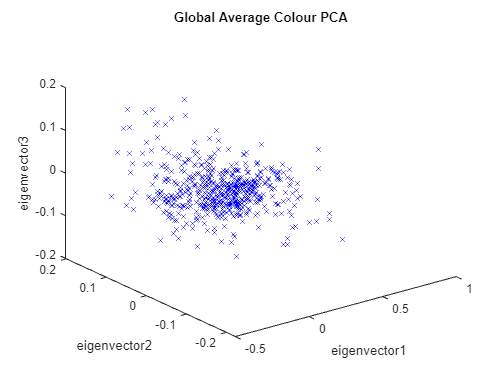

% Build eigen model
[~, eigenDeflated, ALLFEATPCA] = BuildEigenmodel(ALLFEAT);
figure('Name',"Global Average Colour PCA",'NumberTitle','off'); 
PlotPCA(ALLFEATPCA); 
title("Global Average Colour PCA");

## Showcase

### Euclidean Distance

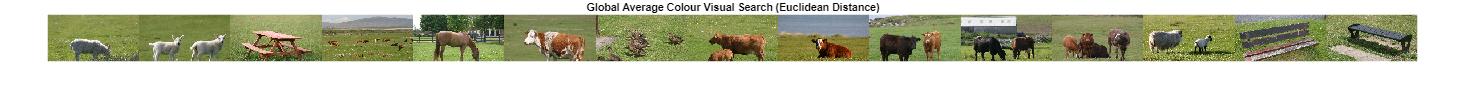

dstAll = GetDistance(queryimg, ALLFEAT, @GetEuclideanDistance);
dst=dstAll(1:SHOW,:);

figure('Name','Global Average Colour Visual Search (Euclidean Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Global Average Colour Visual Search (Euclidean Distance)");

#### Precision and Recall

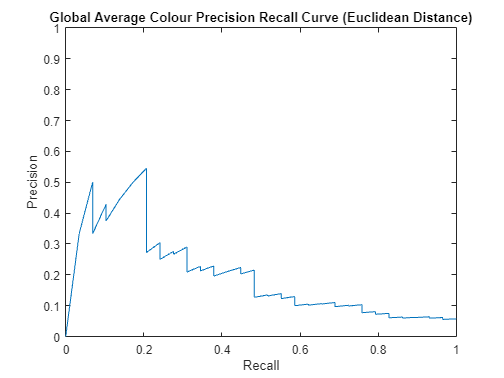

Precision: 0.428571
Recall: 0.206897
Average Precision 0.211212

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Global Average Colour Precision Recall Curve (Euclidean Distance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Global Average Colour Precision Recall Curve (Euclidean Distance)");

### PCA/Euclidean Distance

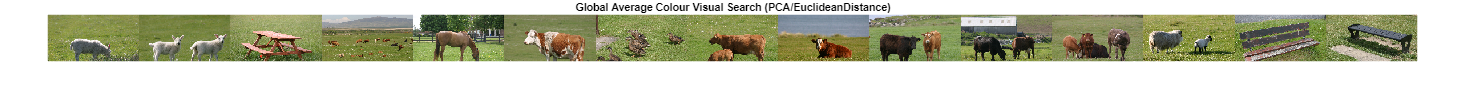

dstAll = GetDistance(queryimg, ALLFEATPCA, @GetEuclideanDistance);
dst=dstAll(1:SHOW,:);

figure('Name','Global Average Colour Visual Search (PCA/EuclideanDistance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Global Average Colour Visual Search (PCA/EuclideanDistance)");

#### Precision and Recall

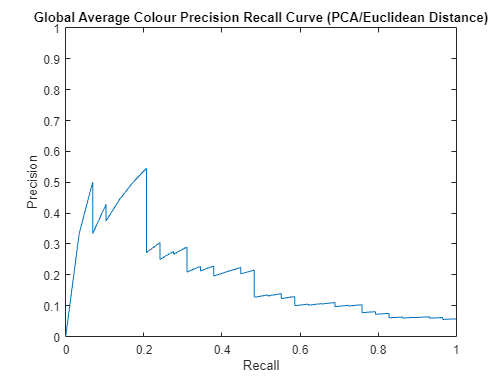

Precision: 0.428571
Recall: 0.206897
Average Precision 0.211212

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Global Average Colour Precision Recall Curve (PCA/Euclidean Distance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Global Average Colour Precision Recall Curve (PCA/Euclidean Distance)");

### PCA/Mahalanobis Distance

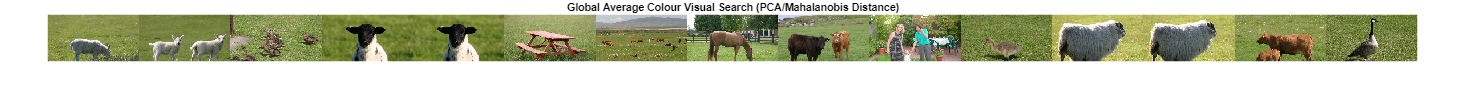

dstAll = GetDistance(queryimg, ALLFEATPCA, @GetMahalanobisDistance, eigenDeflated.val);
dst=dstAll(1:SHOW,:);

figure('Name','Global Average Colour Visual Search (PCA/Mahalanobis Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Global Average Colour Visual Search (PCA/Mahalanobis Distance)");

#### Precision and Recall

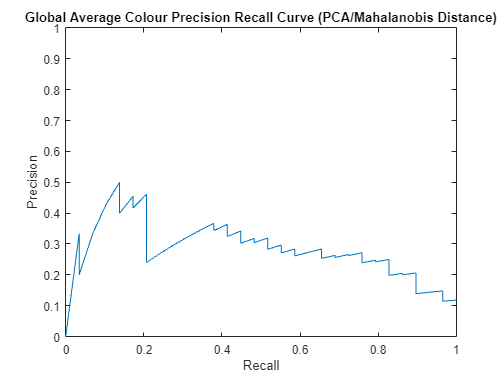

Precision: 0.428571
Recall: 0.206897
Average Precision 0.300279

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Global Average Colour Precision Recall Curve (PCA/Mahalanobis Distance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Global Average Colour Precision Recall Curve (PCA/Mahalanobis Distance)");

### PCA/Manhattan Distance

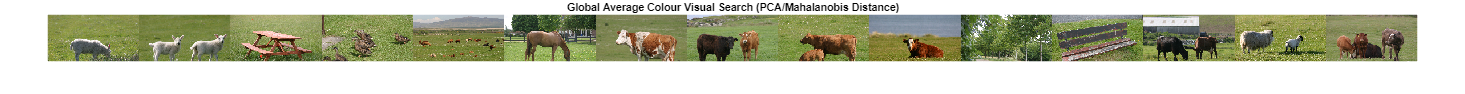

dstAll = GetDistance(queryimg, ALLFEATPCA, @GetManhattanDistance);
dst=dstAll(1:SHOW,:);

figure('Name','Global Average Colour Visual Search (PCA/Manhattan Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Global Average Colour Visual Search (PCA/Mahalanobis Distance)");

#### Precision and Recall

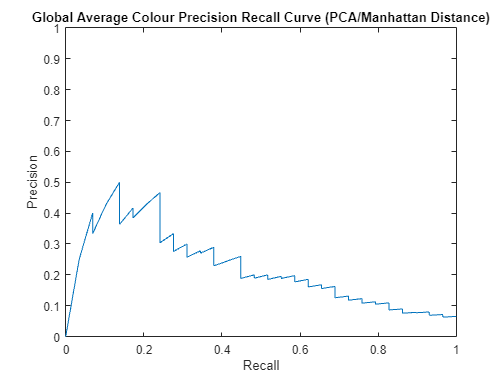

Precision: 0.428571
Recall: 0.206897
Average Precision 0.233305

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Global Average Colour Precision Recall Curve (PCA/Mahalanobis Distance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Global Average Colour Precision Recall Curve (PCA/Manhattan Distance)");

### PCA/Minkowski Distance

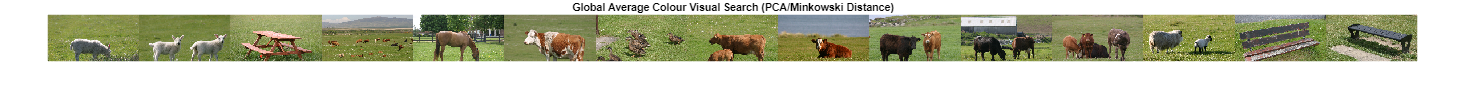

dstAll = GetDistance(queryimg, ALLFEATPCA, @GetMinkowskiDistance, 2);
dst=dstAll(1:SHOW,:);

figure('Name','Global Average Colour Visual Search (PCA/Minkowski Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Global Average Colour Visual Search (PCA/Minkowski Distance)");

#### Precision and Recall

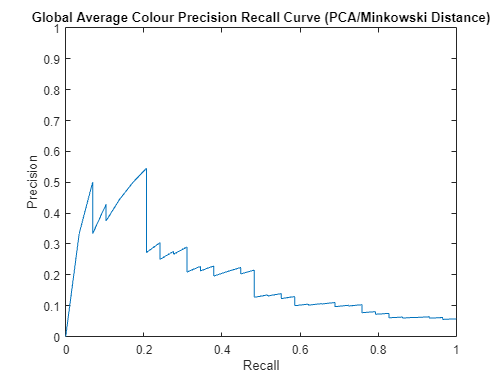

Precision: 0.428571
Recall: 0.206897
Average Precision 0.211212

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Global Average Colour Precision Recall Curve (PCA/Minkowski Distance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Global Average Colour Precision Recall Curve (PCA/Minkowski Distance)");

## Global Average Colour - Precision Recall over dataset

% Load Descriptors
[allfiles, ~, ALLFEAT] = LoadDescriptors(DATASET_FOLDER, DESCRIPTOR_FOLDER, GLOBAL_AVERAGE_RGB_FOLDER);
% Build eigen model
[~, eigenDeflated, ALLFEATPCA] = BuildEigenmodel(ALLFEAT);

### Euclidean Distance

TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
tic;
for i=1:NIMG
    dstAll = GetDistance(i, ALLFEAT, @GetEuclideanDistance);
    [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
    TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
end
toc;

Elapsed time is 22.496640 seconds.


fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n', MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);

Mean Average Precision: 0.120065
Precision: 0.151801
Recall: 0.075493


### PCA/Mahalanobis Distance

TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
tic;
for i=1:NIMG
    dstAll = GetDistance(i, ALLFEATPCA, @GetMahalanobisDistance, eigenDeflated.val);
    [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
    TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
end
toc;

Elapsed time is 21.954456 seconds.


fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n',MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);

Mean Average Precision: 0.149413
Precision: 0.179961
Recall: 0.089961


### PCA/Manhattan Distance

TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
tic;
for i=1:NIMG
    dstAll = GetDistance(i, ALLFEATPCA, @GetManhattanDistance);
    [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
    TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
end
toc;

Elapsed time is 22.179139 seconds.


fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n',MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);

Mean Average Precision: 0.124403
Precision: 0.151317
Recall: 0.075276


### PCA/Minkowski Distance

TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
tic;
for i=1:NIMG
    dstAll = GetDistance(i, ALLFEATPCA, @GetMinkowskiDistance, 2);
    [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
    TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
end
toc;

Elapsed time is 22.036741 seconds.


fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n',MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);

Mean Average Precision: 0.120065
Precision: 0.151801
Recall: 0.075493


# Global RGB Histogram

% Load Descriptors
[allfiles, ALLFILES, ALLFEAT] = LoadDescriptors(DATASET_FOLDER, DESCRIPTOR_FOLDER, GLOBAL_RGB_HISTOGRAM_FOLDER);

## PCA

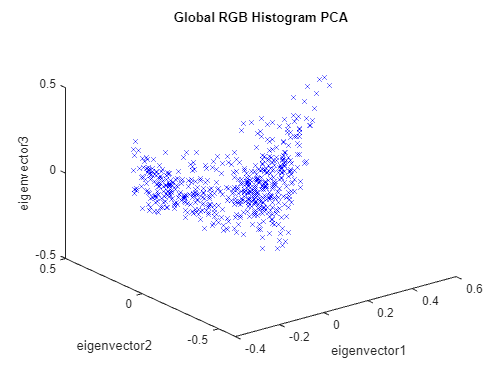

% Build eigen model
[~, eigenDeflated, ALLFEATPCA] = BuildEigenmodel(ALLFEAT);
figure('Name',"Global RGB Histogram PCA",'NumberTitle','off'); PlotPCA(ALLFEATPCA); title("Global RGB Histogram PCA");

## Showcase

### Euclidean Distance

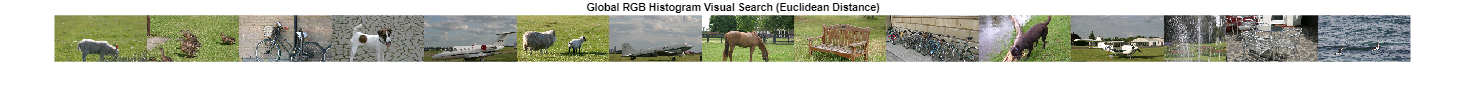

dstAll = GetDistance(queryimg, ALLFEAT, @GetEuclideanDistance);
dst=dstAll(1:SHOW,:);

figure('Name','Global RGB Histogram Visual Search (Euclidean Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Global RGB Histogram Visual Search (Euclidean Distance)");

#### Precision and Recall

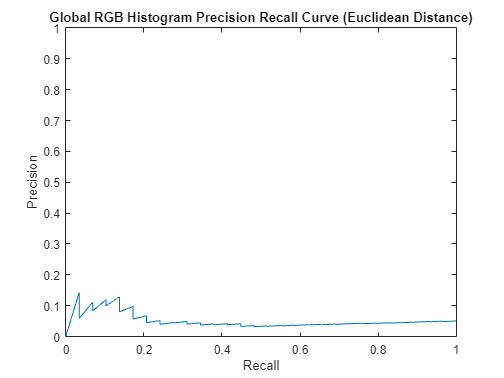

Precision: 0.071429
Recall: 0.034483
Average Precision 0.057241

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Global RGB Histogram Precision Recall Curve (Euclidean Distance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Global RGB Histogram Precision Recall Curve (Euclidean Distance)");

### PCA/Euclidean Distance

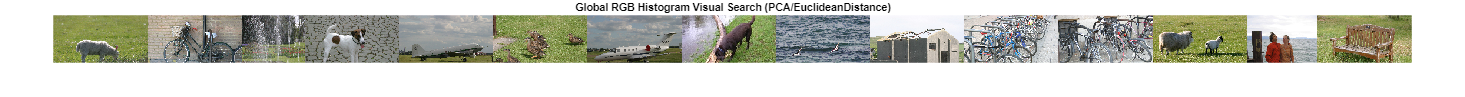

dstAll = GetDistance(queryimg, ALLFEATPCA, @GetEuclideanDistance);
dst=dstAll(1:SHOW,:);

figure('Name','Global RGB Histogram Visual Search (PCA/Euclidean Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Global RGB Histogram Visual Search (PCA/EuclideanDistance)");

#### Precision and Recall

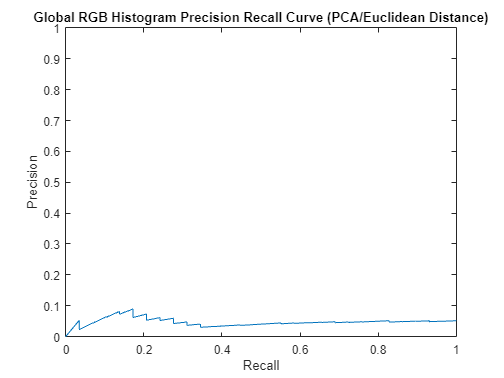

Precision: 0.000000
Recall: 0.000000
Average Precision 0.050906

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Global RGB Histogram Precision Recall Curve (PCA/EuclideanDistance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Global RGB Histogram Precision Recall Curve (PCA/Euclidean Distance)");

### PCA/Mahalanobis Distance

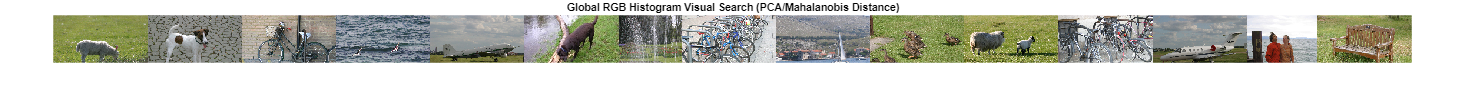

dstAll = GetDistance(queryimg, ALLFEATPCA, @GetMahalanobisDistance, eigenDeflated.val);
dst=dstAll(1:SHOW,:);

figure('Name','Global RGB Histogram Visual Search (PCA/Mahalanobis Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Global RGB Histogram Visual Search (PCA/Mahalanobis Distance)");

#### Precision and Recall

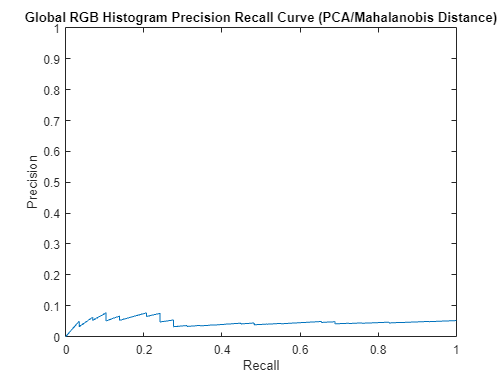

Precision: 0.000000
Recall: 0.000000
Average Precision 0.050372

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Global RGB Histogram Precision Recall Curve (PCA/Mahalanobis Distance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Global RGB Histogram Precision Recall Curve (PCA/Mahalanobis Distance)");

### PCA/Manhattan Distance

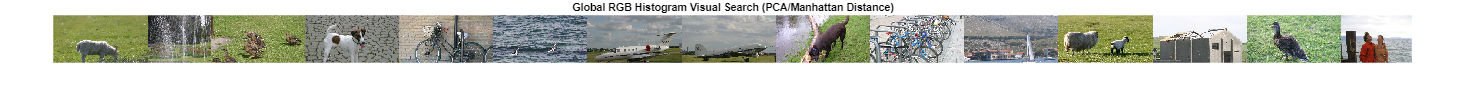

dstAll = GetDistance(queryimg, ALLFEATPCA, @GetManhattanDistance);
dst=dstAll(1:SHOW,:);

figure('Name','Global RGB Histogram Visual Search (PCA/Manhattan Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Global RGB Histogram Visual Search (PCA/Manhattan Distance)");

#### Precision and Recall

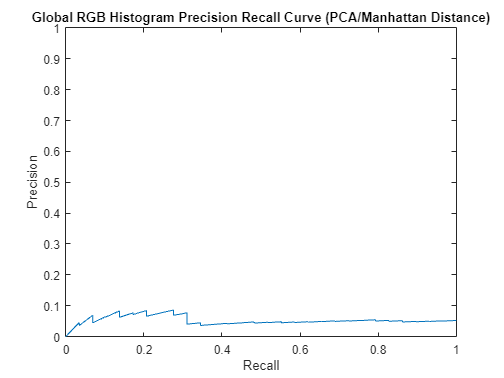

Precision: 0.000000
Recall: 0.000000
Average Precision 0.056480

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Global RGB Histogram Precision Recall Curve (PCA/Manhattan Distance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Global RGB Histogram Precision Recall Curve (PCA/Manhattan Distance)");

### PCA/Minkowski Distance

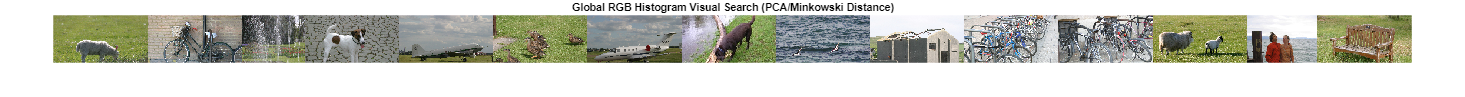

dstAll = GetDistance(queryimg, ALLFEATPCA, @GetMinkowskiDistance, 2);
dst=dstAll(1:SHOW,:);

figure('Name','Global RGB Histogram Visual Search (PCA/Minkowski Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Global RGB Histogram Visual Search (PCA/Minkowski Distance)");

#### Precision and Recall

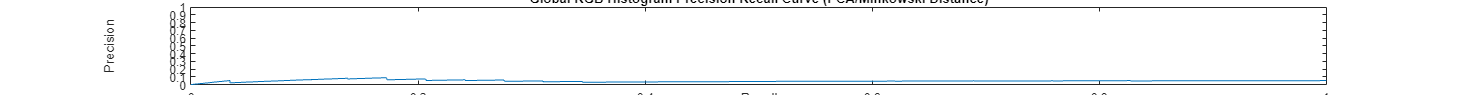

Precision: 0.000000
Recall: 0.000000
Average Precision 0.050906

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Global RGB Histogram Precision Recall Curve (PCA/Minkowski Distance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Global RGB Histogram Precision Recall Curve (PCA/Minkowski Distance)");

## Global RGB Histogram - Precision Recall over dataset

% Load Descriptors
[allfiles, ~, ALLFEAT] = LoadDescriptors(DATASET_FOLDER, DESCRIPTOR_FOLDER, GLOBAL_RGB_HISTOGRAM_FOLDER);
% Build eigen model
[~, eigenDeflated, ALLFEATPCA] = BuildEigenmodel(ALLFEAT);

### Euclidean Distance

TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
tic;
for i=1:NIMG
    dstAll = GetDistance(i, ALLFEAT, @GetEuclideanDistance);
    [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
    TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
end
toc;

Elapsed time is 22.247956 seconds.


fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n', MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);

Mean Average Precision: 0.118339
Precision: 0.147933
Recall: 0.072311


### PCA/Mahalanobis Distance

TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
tic;
for i=1:NIMG
    dstAll = GetDistance(i, ALLFEATPCA, @GetMahalanobisDistance, eigenDeflated.val);
    [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
    TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
end
toc;

Elapsed time is 21.660943 seconds.


fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n', MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);

Mean Average Precision: 0.098598
Precision: 0.111554
Recall: 0.054390


### PCA/Manhattan Distance

TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
tic;
for i=1:NIMG
    dstAll = GetDistance(i, ALLFEATPCA, @GetManhattanDistance);
    [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
    TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
end
toc;

Elapsed time is 22.733110 seconds.


fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n', MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);

Mean Average Precision: 0.101732
Precision: 0.117235
Recall: 0.057166


### PCA/Minkowski Distance

TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
tic;
for i=1:NIMG
    dstAll = GetDistance(i, ALLFEATPCA, @GetMinkowskiDistance, 2);
    [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
    TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
end
toc;

Elapsed time is 22.105951 seconds.


fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n', MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);

Mean Average Precision: 0.100825
Precision: 0.115784
Recall: 0.056399


# Edge Orientation Histogram

% Load Descriptors
[allfiles, ALLFILES, ALLFEAT] = LoadDescriptors(DATASET_FOLDER, DESCRIPTOR_FOLDER, GLOBAL_RGB_HISTOGRAM_FOLDER);

## PCA

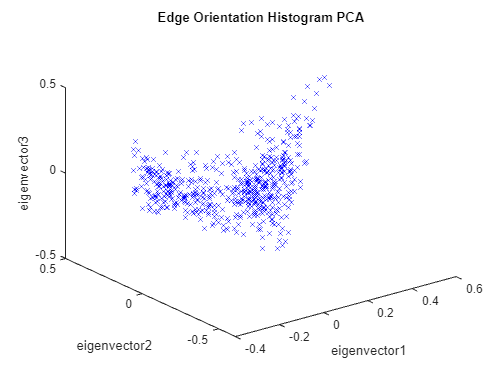

% Build eigen model
[~, eigenDeflated, ALLFEATPCA] = BuildEigenmodel(ALLFEAT);
figure('Name',"Edge Orientation Histogram PCA",'NumberTitle','off'); PlotPCA(ALLFEATPCA); title("Edge Orientation Histogram PCA");

## Showcase

### Euclidean Distance

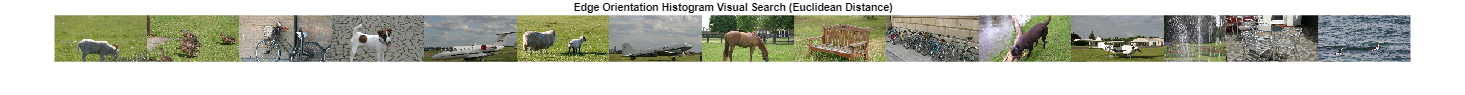

dstAll = GetDistance(queryimg, ALLFEAT, @GetEuclideanDistance);
dst=dstAll(1:SHOW,:);

figure('Name','Edge Orientation Histogram Visual Search (Euclidean Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Edge Orientation Histogram Visual Search (Euclidean Distance)");

#### Precision and Recall

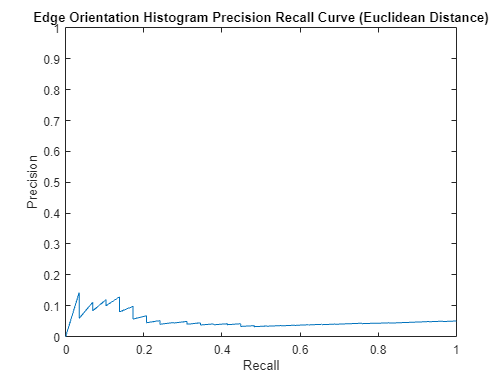

Precision: 0.071429
Recall: 0.034483
Average Precision 0.057241

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Edge Orientation Histogram Precision Recall Curve (Euclidean Distance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Edge Orientation Histogram Precision Recall Curve (Euclidean Distance)");

### PCA/Euclidean Distance

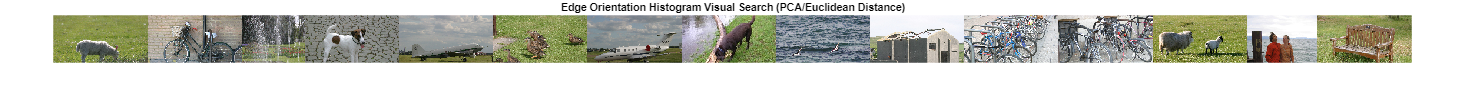

dstAll = GetDistance(queryimg, ALLFEATPCA, @GetEuclideanDistance);
dst=dstAll(1:SHOW,:);

figure('Name','Edge Orientation Histogram Visual Search (PCA/Euclidean Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Edge Orientation Histogram Visual Search (PCA/Euclidean Distance)");

#### Precision and Recall

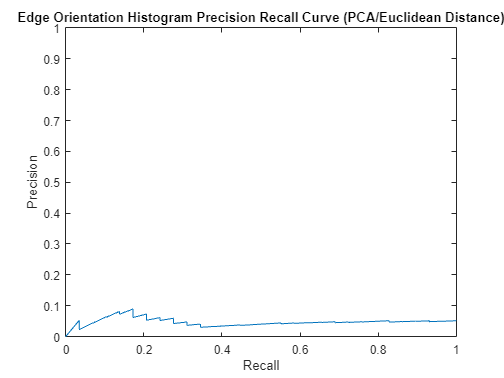

Precision: 0.000000
Recall: 0.000000
Average Precision 0.050906

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Edge Orientation Histogram Precision Recall Curve (PCA/Euclidean Distance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Edge Orientation Histogram Precision Recall Curve (PCA/Euclidean Distance)");

### PCA/Mahalanobis Distance

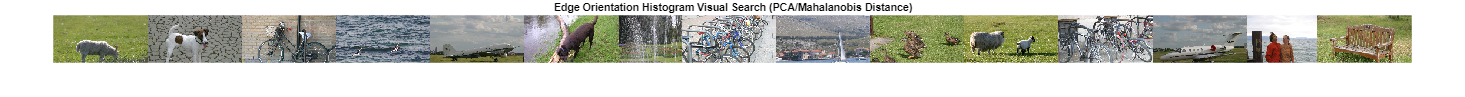

dstAll = GetDistance(queryimg, ALLFEATPCA, @GetMahalanobisDistance, eigenDeflated.val);
dst=dstAll(1:SHOW,:);

figure('Name','Edge Orientation Histogram Visual Search (PCA/Mahalanobis Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Edge Orientation Histogram Visual Search (PCA/Mahalanobis Distance)");

#### Precision and Recall

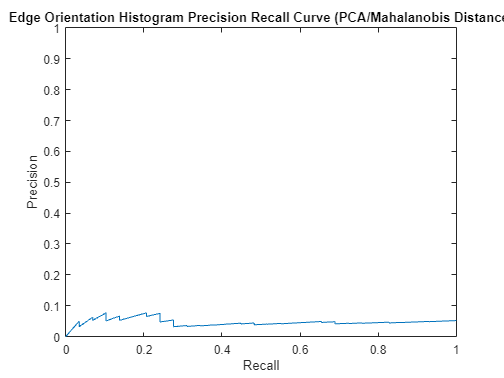

Precision: 0.000000
Recall: 0.000000
Average Precision 0.050372

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Edge Orientation Histogram Precision Recall Curve (PCA/Mahalanobis Distance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Edge Orientation Histogram Precision Recall Curve (PCA/Mahalanobis Distance)");

### PCA/Manhattan Distance

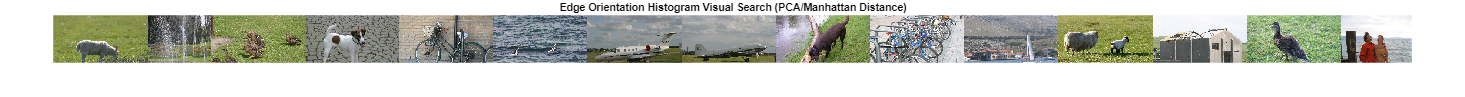

dstAll = GetDistance(queryimg, ALLFEATPCA, @GetManhattanDistance);
dst=dstAll(1:SHOW,:);

figure('Name','Edge Orientation Histogram Visual Search (PCA/Manhattan Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Edge Orientation Histogram Visual Search (PCA/Manhattan Distance)");

#### Precision and Recall

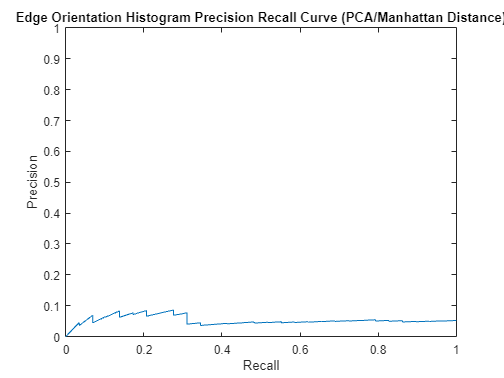

Precision: 0.000000
Recall: 0.000000
Average Precision 0.056480

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Edge Orientation Histogram Precision Recall Curve (PCA/Manhattan Distance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Edge Orientation Histogram Precision Recall Curve (PCA/Manhattan Distance)");

### PCA/Minkowski Distance

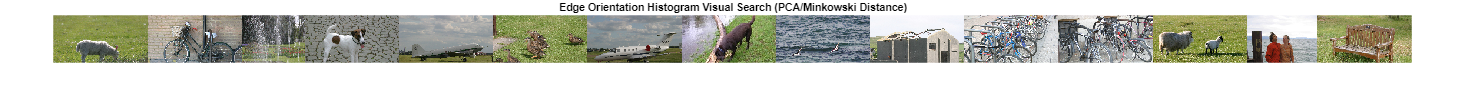

dstAll = GetDistance(queryimg, ALLFEATPCA, @GetMinkowskiDistance, 2);
dst=dstAll(1:SHOW,:);

figure('Name','Edge Orientation Histogram Visual Search (PCA/Minkowski Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Edge Orientation Histogram Visual Search (PCA/Minkowski Distance)");

#### Precision and Recall

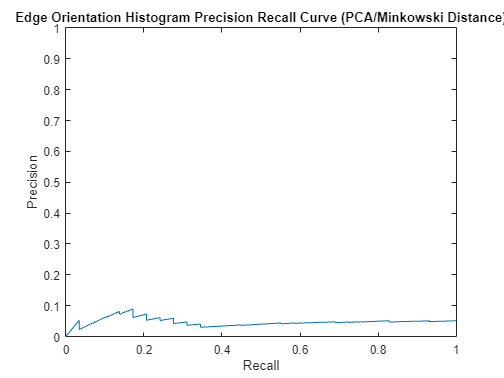

Precision: 0.000000
Recall: 0.000000
Average Precision 0.050906

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Edge Orientation Histogram Precision Recall Curve (PCA/Minkowski Distance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Edge Orientation Histogram Precision Recall Curve (PCA/Minkowski Distance)");

## Edge Orientation Histogram - Precision Recall over dataset

% Load Descriptors
[allfiles, ~, ALLFEAT] = LoadDescriptors(DATASET_FOLDER, DESCRIPTOR_FOLDER, GLOBAL_RGB_HISTOGRAM_FOLDER);
% Build eigen model
[~, eigenDeflated, ALLFEATPCA] = BuildEigenmodel(ALLFEAT);

### Euclidean Distance

TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
tic;
for i=1:NIMG
    dstAll = GetDistance(i, ALLFEAT, @GetEuclideanDistance);
    [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
    TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
end
toc;

Elapsed time is 21.731717 seconds.


fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n', MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);

Mean Average Precision: 0.118339
Precision: 0.147933
Recall: 0.072311


### PCA/Mahalanobis Distance

TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
tic;
for i=1:NIMG
    dstAll = GetDistance(i, ALLFEATPCA, @GetMahalanobisDistance, eigenDeflated.val);
    [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
    TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
end
toc;

Elapsed time is 21.319408 seconds.


fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n', MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);

Mean Average Precision: 0.098598
Precision: 0.111554
Recall: 0.054390


### PCA/Manhattan Distance

TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
tic;
for i=1:NIMG
    dstAll = GetDistance(i, ALLFEATPCA, @GetManhattanDistance);
    [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
    TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
end
toc;

Elapsed time is 21.949044 seconds.


fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n', MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);

Mean Average Precision: 0.101732
Precision: 0.117235
Recall: 0.057166


### PCA/Minkowski Distance

TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
tic;
for i=1:NIMG
    dstAll = GetDistance(i, ALLFEATPCA, @GetMinkowskiDistance, 2);
    [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
    TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
end
toc;

Elapsed time is 21.831725 seconds.


fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n', MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);

Mean Average Precision: 0.100825
Precision: 0.115784
Recall: 0.056399


# Spatial Grid - Edge Orinetation + Average RGB Colour

% Load Descriptors
[allfiles, ALLFILES, ALLFEAT] = LoadDescriptors(DATASET_FOLDER, DESCRIPTOR_FOLDER, SPATIAL_GRID_FOLDER);

## PCA

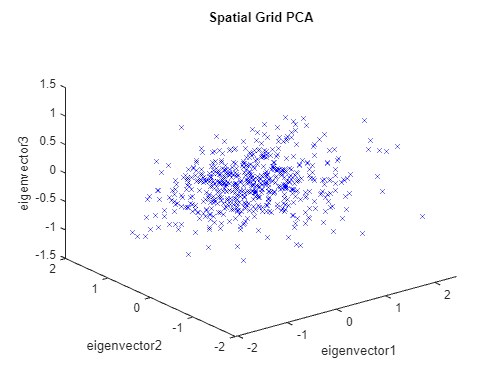

% Build eigen model
[eigenBuild, eigenDeflated, ALLFEATPCA] = BuildEigenmodel(ALLFEAT);
figure('Name',"Spatial Grid PCA",'NumberTitle','off'); PlotPCA(ALLFEATPCA); title("Spatial Grid PCA");

## Showcase

### Euclidean Distance

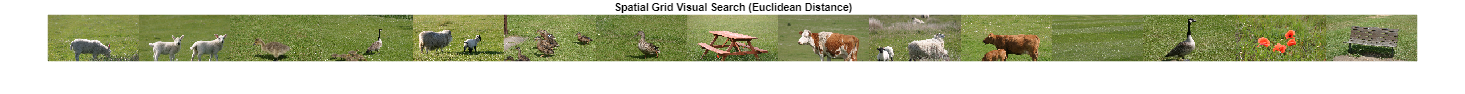

dstAll = GetDistance(queryimg, ALLFEAT, @GetEuclideanDistance);
dst=dstAll(1:SHOW,:);

figure('Name','Spatial Grid Visual Search (Euclidean Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Spatial Grid Visual Search (Euclidean Distance)");

#### Precision and Recall

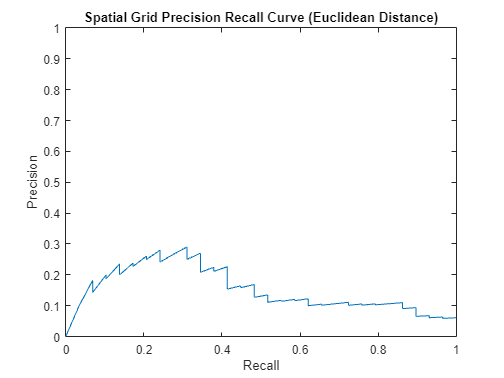

Precision: 0.142857
Recall: 0.068966
Average Precision 0.160014

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Spatial Grid Precision Recall Curve (Euclidean Distance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Spatial Grid Precision Recall Curve (Euclidean Distance)");

### PCA/Euclidean Distance

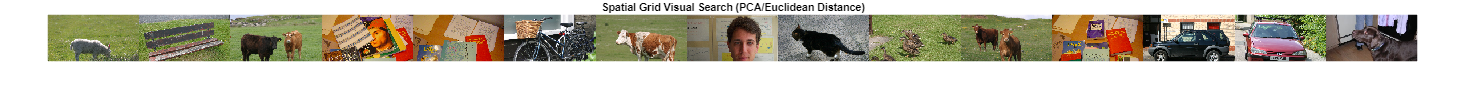

dstAll = GetDistance(queryimg, ALLFEATPCA, @GetEuclideanDistance);
dst=dstAll(1:SHOW,:);

figure('Name','Spatial Grid Visual Search (PCA/Euclidean Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Spatial Grid Visual Search (PCA/Euclidean Distance)");

#### Precision and Recall

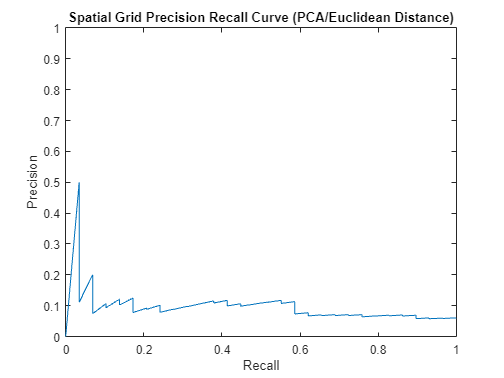

Precision: 0.142857
Recall: 0.068966
Average Precision 0.108483

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Spatial Grid Precision Recall Curve (PCA/Euclidean Distance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Spatial Grid Precision Recall Curve (PCA/Euclidean Distance)");

### PCA/Mahalanobis Distance

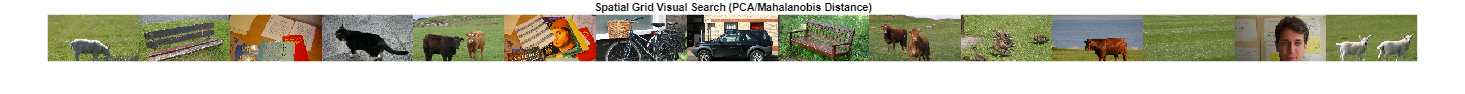

dstAll = GetDistance(queryimg, ALLFEATPCA, @GetMahalanobisDistance, eigenDeflated.val);
dst=dstAll(1:SHOW,:);

figure('Name','Spatial Grid Visual Search (PCA/Mahalanobis Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Spatial Grid Visual Search (PCA/Mahalanobis Distance)");

#### Precision and Recall

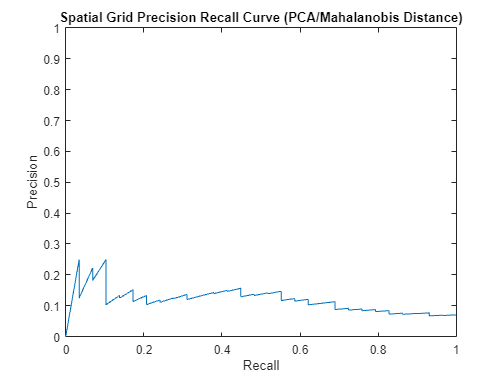

Precision: 0.214286
Recall: 0.103448
Average Precision 0.128014

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Spatial Grid Precision Recall Curve (PCA/Mahalanobis Distance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Spatial Grid Precision Recall Curve (PCA/Mahalanobis Distance)");

### PCA/Manhattan Distance

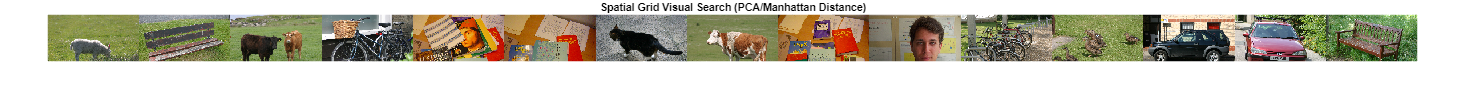

dstAll = GetDistance(queryimg, ALLFEATPCA, @GetManhattanDistance);
dst=dstAll(1:SHOW,:);

figure('Name','Spatial Grid Visual Search (PCA/Manhattan Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Spatial Grid Visual Search (PCA/Manhattan Distance)");

#### Precision and Recall

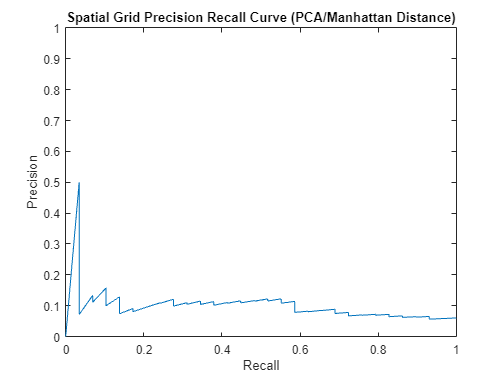

Precision: 0.071429
Recall: 0.034483
Average Precision 0.111732

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Spatial Grid Precision Recall Curve (PCA/Manhattan Distance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Spatial Grid Precision Recall Curve (PCA/Manhattan Distance)");

### PCA/Minkowski Distance

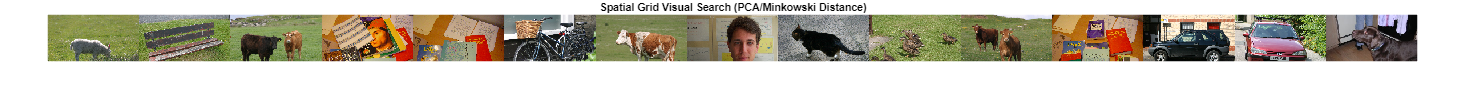

dstAll = GetDistance(queryimg, ALLFEATPCA, @GetMinkowskiDistance, 2);
dst=dstAll(1:SHOW,:);

figure('Name','Spatial Grid Visual Search (PCA/Minkowski Distance)','NumberTitle','off');
imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
title("Spatial Grid Visual Search (PCA/Minkowski Distance)");

#### Precision and Recall

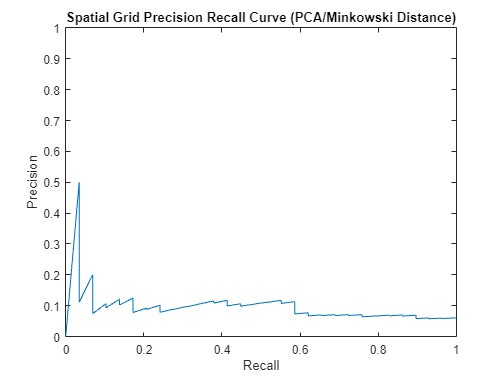

Precision: 0.142857
Recall: 0.068966
Average Precision 0.108483

[precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
figure('Name','Spatial Grid Precision Recall Curve (PCA/Minkowski Distance)','NumberTitle','off');
PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision, precision, recall); title("Spatial Grid Precision Recall Curve (PCA/Minkowski Distance)");

## Spatial Grid - Edge Orinetation + Average RGB Colour - Precision Recall over dataset

% Load Descriptors
[allfiles, ~, ALLFEAT] = LoadDescriptors(DATASET_FOLDER, DESCRIPTOR_FOLDER, SPATIAL_GRID_FOLDER);
% Build eigen model
[~, eigenDeflated, ALLFEATPCA] = BuildEigenmodel(ALLFEAT);

### Euclidean Distance

TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
tic;
for i=1:NIMG
    dstAll = GetDistance(i, ALLFEAT, @GetEuclideanDistance);
    [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
    TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
end
toc;

Elapsed time is 21.915688 seconds.


fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n', MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);

Mean Average Precision: 0.167774
Precision: 0.223834
Recall: 0.110241


### PCA/Mahalanobis Distance

TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
tic;
for i=1:NIMG
    dstAll = GetDistance(i, ALLFEATPCA, @GetMahalanobisDistance, eigenDeflated.val);
    [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
    TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
end
toc;

Elapsed time is 21.844629 seconds.


fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n', MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);

Mean Average Precision: 0.120764
Precision: 0.138869
Recall: 0.067783


### PCA/Manhattan Distance

TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
tic;
for i=1:NIMG
    dstAll = GetDistance(i, ALLFEATPCA, @GetManhattanDistance);
    [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
    TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
end
toc;

Elapsed time is 21.903441 seconds.


fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n', MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);

Mean Average Precision: 0.116623
Precision: 0.138144
Recall: 0.067304


### PCA/Minkowski Distance

TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
tic;
for i=1:NIMG
    dstAll = GetDistance(i, ALLFEATPCA, @GetMinkowskiDistance, 2);
    [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
    TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
end
toc;

Elapsed time is 21.389035 seconds.


fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n', MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);

Mean Average Precision: 0.116512
Precision: 0.140682
Recall: 0.068575


# Helper Functions

function outdisplay = GenerateVisualSearchDisplay(dst, ALLFILES)
    outdisplay=[];
    for i=1:size(dst,1)
        img=imread(ALLFILES{dst(i,2)});
        img=img(1:2:end,1:2:end,:); % make image a quarter size
        img=img(1:81,:,:); % crop image to uniform size vertically (some MSVC images are different heights)
        outdisplay=[outdisplay img];
    end
end


function PlotPCA(ALLFEATPCA)
    plot3(ALLFEATPCA(:,1),ALLFEATPCA(:,2),ALLFEATPCA(:,3),'bx');
    xlabel('eigenvector1');
    ylabel('eigenvector2');
    zlabel('eigenvector3');
end

function PrecisionRecallInfoDisplay(precisionRecallMat, averagePrecision,  precision, recall)
    plot(precisionRecallMat(:, 2), precisionRecallMat(:, 1));
    axis([0 1 0 1])
    xlabel('Recall');
    ylabel('Precision');
    
    fprintf('Precision: %f\nRecall: %f\nAverage Precision %f', precision, recall, averagePrecision);
end